# **Project Two Template**

## MAT-350: Applied Linear Algebra

## *Dakota Keyes*

## *2/15/2023*

# **Problem 1**

**Use the svd() function **in MATLAB to compute $A_{1}$, the **rank-1 approximation of **$A$**. **Clearly state what $A_{1}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{1}$.

### Solution:

%code for 3x3 matrix

A=[1 2 3; 3 3 4; 5 6 7];

%SVD function to get results on A
[U S V] = svd(A);

%Rank 1 approx of A
A1 = u(:,1:1)*s(1:1,1:1)*v(:,1:1)' 

A1 =     1.3889    1.7059    1.9807
    3.3118    4.0678    4.7230
    5.7253    7.0322    8.1649


%Rank = 1
rank(A1)

ans = 1

% Calculating RSME between A, A1
RMSE = rms(sqrt(mean((A - A1).^2)))

RMSE = 0.8155

# **Problem 2**

**Use the svd() function** in MATLAB to compute $A_{2}$, the** rank-2 approximation of **$A$. Clearly state what $A_{2}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{2}$. Which approximation is better, $A_{1}$ or $A_{2}$? Explain.

### Solution:

%code
%A2 to find rank 2 approx
A2 = u(:,1:2)*s(1:2,1:2)*v(:,1:2)'

A2 =     1.0100    1.8213    2.1469
    2.9907    4.1656    4.8639
    6.0029    6.9476    8.0431


%Verifying rank
rank(A2)

ans = 2

% Calculating RSME between A, A2
RSME2 = norm(A-A2,'fro')/(3*3)

RSME2 = 0.2689

**Explain: **

# **Problem 3**

For the $3 \times 3$ matrix $A$, the singular value decomposition is $A=USV'$ where $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$. Use MATLAB to **compute **the dot product $d_{1}=dot(\mathbf{u}_{1},\mathbf{u}_{2})$.  

Also, use MATLAB to **compute **the cross product $\mathbf{c} =cross(\mathbf{u}_{1},\mathbf{u}_{2})$ and dot product $d_{2} = dot(\mathbf{c},\mathbf{u}_{3})$. Clearly state the values for each of these computations. Do these values make sense? **Explain**.

### Solution:

%code
%Seperating U into vectors to apply cross & dot product 
U1 = [-0.2055; -0.4900; -0.8471]

U1 =    -0.2055
   -0.4900
   -0.8471


U2 = [-0.6658; -0.5644; 0.4880]

U2 =    -0.6658
   -0.5644
    0.4880


U3 = [-0.7172; 0.6643; -0.2103]

U3 =    -0.7172
    0.6643
   -0.2103


%Calculating dot product 1
d1 = dot(U1,U2)

d1 = -6.9000e-06

% Calculating cross product
c = cross(U1,U2)

c =    -0.7172
    0.6643
   -0.2103


%dot product
d2 = dot(c,U3)

d2 = 0.9999

**Explain:**

# **Problem 4**

Using the matrix $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$, d**etermine whether or not the columns of **$U$ **span **$\mathbb{R}^{3}$. **Explain your approach.**

### Solution:

%code
%Column vectors back into U
U = [U1 U2 U3]

U =    -0.2055   -0.6658   -0.7172
   -0.4900   -0.5644    0.6643
   -0.8471    0.4880   -0.2103


% 3 pivot columns in the matrix
reducedU = rref(U)

reducedU =      1     0     0
     0     1     0
     0     0     1


% Function to check the rank of reduced U matrix
rank(reducedU)

ans = 3

**Explain:** 

# **Problem 5**

Use the MATLAB imshow() function to load and display the image $A$ stored in the image.mat file, available in the Project Two Supported Materials area in Brightspace. For the loaded image, **derive the value of **$k$ that will result in a compression ratio of $CR \approx 2$. For this value of $k$, **construct the rank-*****k***** approximation of the image**. 

### Solution:

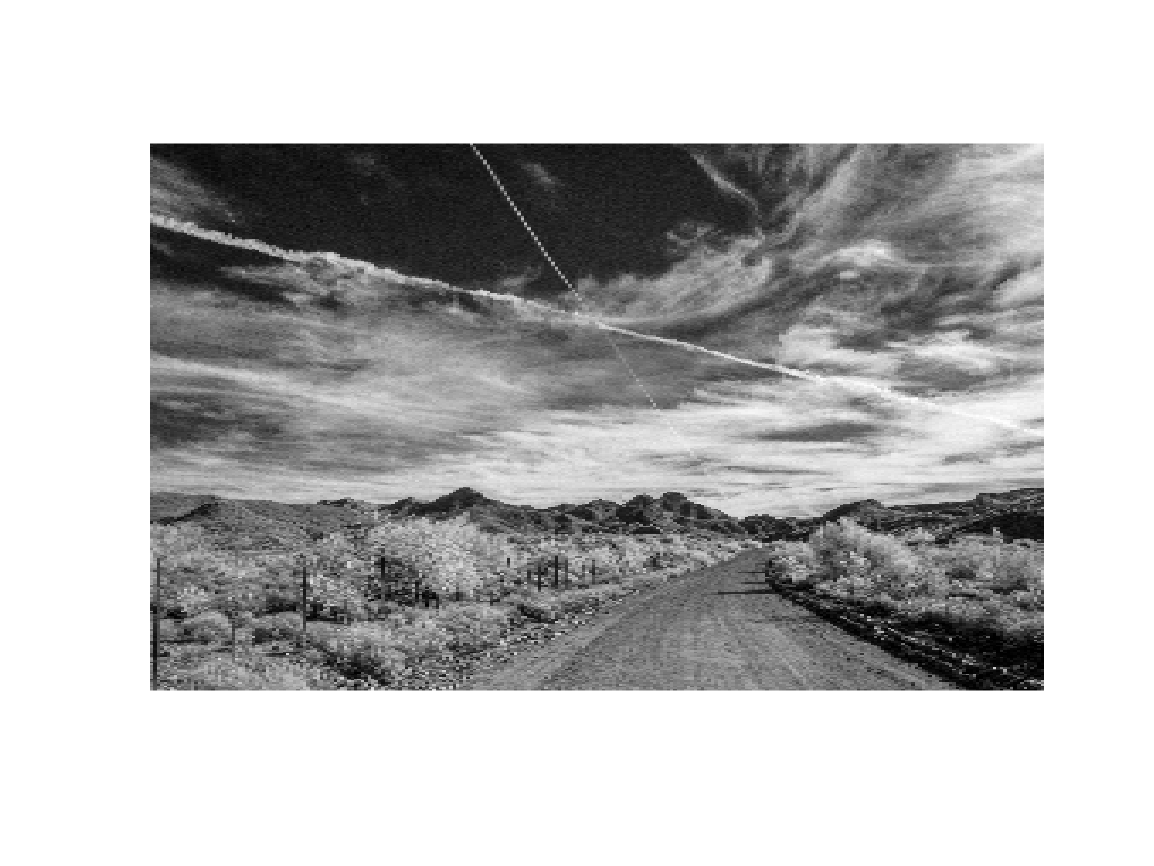

%code

% Load the image from the .mat file
load image.mat

%Dimensions (2583 x 4220)
figure;
imshow(A)



% Use the SVD function

[U, S, V] = svd(double(A))

U =    -0.0106   -0.0360   -0.0006    0.0032   -0.0032    0.0041   -0.0066    0.0022   -0.0199    0.0059   -0.0138    0.0154    0.0124   -0.0102    0.0118   -0.0036    0.0034   -0.0066    0.0026   -0.0069    0.0064   -0.0004    0.0112   -0.0049   -0.0202    0.0061   -0.0107   -0.0005   -0.0045    0.0149   -0.0130    0.0065    0.0079   -0.0008    0.0031   -0.0212    0.0101   -0.0000    0.0199   -0.0029    0.0033   -0.0077    0.0066   -0.0047    0.0143   -0.0025    0.0156   -0.0202    0.0147   -0.0111
   -0.0105   -0.0361   -0.0006    0.0030   -0.0035    0.0049   -0.0062    0.0020   -0.0204    0.0058   -0.0139    0.0152    0.0122   -0.0092    0.0112   -0.0030    0.0026   -0.0074    0.0018   -0.0079    0.0065   -0.0003    0.0109   -0.0046   -0.0191    0.0068   -0.0109   -0.0018   -0.0046    0.0145   -0.0117    0.0065    0.0084   -0.0024    0.0014   -0.0215    0.0104   -0.0006    0.0188   -0.0016    0.0002   -0.0099    0.0067   -0.0059    0.0139   -0.0035    0.0148   -0.0191    0.0160   -0

S = 1.0e+05 *

    4.0600         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.8702         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

V =    -0.0130    0.0044   -0.0358    0.0028   -0.0085    0.0177    0.0128   -0.0163    0.0298    0.0045   -0.0006    0.0122   -0.0143   -0.0020   -0.0278   -0.0168   -0.0247    0.0296    0.0061   -0.0127   -0.0002    0.0341    0.0001    0.0281   -0.0342    0.0119   -0.0180    0.0288    0.0170    0.0066    0.0389    0.0040    0.0194    0.0004    0.0153   -0.0092   -0.0073    0.0082   -0.0234    0.0223   -0.0039    0.0161   -0.0252    0.0082   -0.0099   -0.0221   -0.0117    0.0063   -0.0117   -0.0623
   -0.0130    0.0045   -0.0357    0.0024   -0.0079    0.0184    0.0134   -0.0162    0.0309    0.0038   -0.0012    0.0120   -0.0149   -0.0027   -0.0256   -0.0158   -0.0245    0.0296    0.0086   -0.0136   -0.0003    0.0356   -0.0005    0.0279   -0.0357    0.0122   -0.0190    0.0286    0.0170    0.0083    0.0401    0.0037    0.0168    0.0027    0.0141   -0.0088   -0.0065    0.0056   -0.0205    0.0219   -0.0031    0.0151   -0.0232    0.0073   -0.0127   -0.0161   -0.0120    0.0054   -0.0119   -0

%Finding k value so CR = approx 2
% k = 801 so CR  = 2.000
CR = (2583*4220)/(801*(2583 + 4220 + 1))

CR = 2.0000

%After finding K value, we must calculate the rank (801)
A801 = U(:,1:801) * S(1:801, 1:801) * V(:,1:801)'

A801 =    26.4896   27.2541   30.5810   28.9530   23.3828   25.7705   35.1037   29.3968   32.9167   35.7277   29.6657   25.5423   31.8075   27.1097   27.9802   33.7315   31.1819   30.8813   27.8016   20.0656   19.7837   30.7982   31.4131   27.6530   26.5889   30.2995   31.2249   25.9122   32.7232   31.2294   23.0459   19.7503   33.1269   31.7624   37.3639   32.4922   27.4063   28.1858   23.7386   21.9973   22.4652   26.4795   27.0546   19.7551   22.2834   24.8839   22.4499   23.8428   28.9766   23.6715
   32.6831   34.0733   28.4258   30.5682   27.6882   28.4547   35.6629   31.2002   29.6536   27.3993   22.4987   27.5956   39.5807   33.7341   33.5815   34.0165   32.8017   33.0654   28.2675   17.3682   21.3168   29.9663   27.9044   25.2467   24.2990   26.7841   35.5123   33.3932   29.3797   25.7284   22.1742   18.5305   27.7917   32.7620   35.3463   29.3516   29.6410   27.8408   22.1847   24.3495   24.1099   24.3442   24.2253   20.3470   22.3034   26.3346   20.6531   15.8503   24.3454  

%Verifying rank
rank(A801)

ans = 801

%Revert back to uint8 to display the image
A801 = uint8(round(A801))

A801 = 2583×4220 uint8 matrix
   26   27   31   29   23   26   35   29   33   36   30   26   32   27   28   34   31   31   28   20   20   31   31   28   27   30   31   26   33   31   23   20   33   32   37   32   27   28   24   22   22   26   27   20   22   25   22   24   29   24
   33   34   28   31   28   28   36   31   30   27   22   28   40   34   34   34   33   33   28   17   21   30   28   25   24   27   36   33   29   26   22   19   28   33   35   29   30   28   22   24   24   24   24   20   22   26   21   16   24   23
   36   31   19   20   20   17   25   26   30   23   22   27   35   35   37   34   28   29   29   27   26   29   28   23   24   24   34   38   30   23   20   21   23   26   35   35   32   31   28   29   30   31   29   20   22   28   27   24   22   22
   34   30   26   30   27   16   25   26   28   25   22   24   33   35   32   30   25   29   31   32   31   32   33   26   34   26   27   33   32   23   24   27   26   24   37   46   38   39   36   30   30   29   24  

**Explain:**

%First, we had to load the image in order to determine the M & N values 2583 x 4220.
%Then I had to convert this into a matrix uint8 to a double in order to utilize the SVD function.
%Then, I derived the value of k, that made the compression = 2.

# **Problem 6**

**Display the image and compute** the root mean square error (RMSE) between the approximation and the original image. Make sure to include a copy of the approximate image in your report.

### Solution:

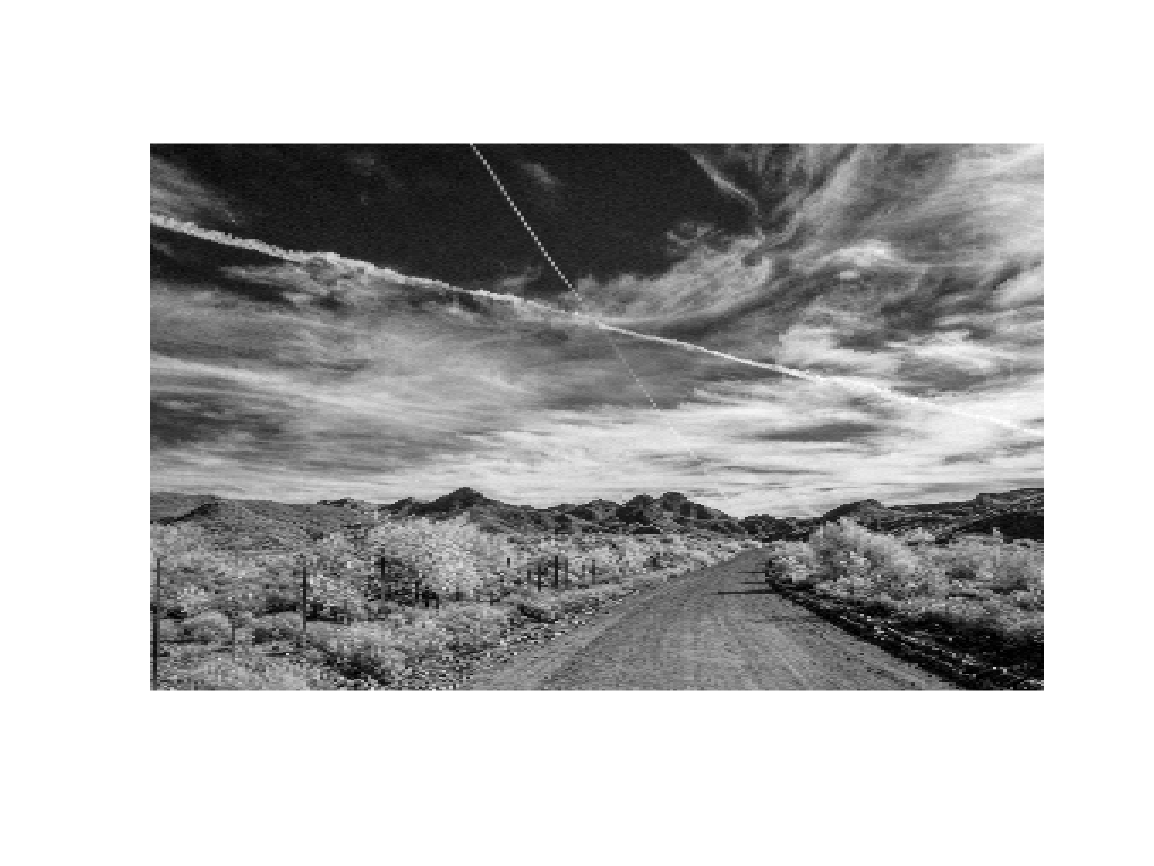

%code
% image for rank 801
imshow(A801)

%Calulating the RSME function on rank 801
RSME801 = norm(double(A)-double(A801),'fro')/(2583 * 4220)

RSME801 = 9.5906e-04

# **Problem 7**

**Repeat** Problems 5 and 6 for $CR \approx 10$, $CR \approx 25$, and $CR \approx 75$. **Explain** what trends you observe in the image approximation as $CR$ increases and provide your recommendation for the best $CR$ based on your observations. Make sure to include a copy of the approximate images in your report.

### Solution:

%code
%Finding k, that CR = 10 (approx)
CR = (2583*4220)/(160*(2583 + 4220 + 1))

CR = 10.0127

%Function for calculating rank 160
A160 = U(:,1:160) * S(1:160, 1:160) * V(:,1:160)'

A160 =    29.0415   29.0508   30.3481   28.6840   28.4125   25.8146   26.5310   25.2709   27.6396   26.6353   26.3993   24.9636   27.9926   27.0146   27.2179   28.2768   25.9639   31.6245   33.9243   36.2018   34.1591   38.5322   38.7773   38.1445   35.1730   35.6000   34.9717   36.1161   34.2159   30.8761   29.4338   29.7744   30.5431   29.6035   30.4288   29.8007   32.5882   31.4661   30.6199   29.4874   27.9186   24.6612   23.8488   20.8052   18.6251   19.9004   18.0891   18.2232   17.8039   17.9542
   29.4990   29.1068   29.9563   28.2658   28.2759   26.2124   27.5634   26.0996   27.8406   27.0115   26.4659   24.8788   27.6099   27.1025   27.7158   28.5169   26.3589   30.9655   33.0725   34.8847   32.9716   37.4344   38.3388   37.9230   35.5901   35.3901   34.7072   35.4735   33.4196   29.3834   27.8350   27.9878   28.3393   27.5154   28.6525   28.3114   30.7299   29.7775   28.4915   27.6666   26.1794   23.4802   22.8002   21.0920   19.2470   20.5765   18.8398   19.2556   19.1044  

%Verifying the rank
rank(A160)

ans = 160

%Converting to uint8
A160 = uint8(round(A160))

A160 = 2583×4220 uint8 matrix
   29   29   30   29   28   26   27   25   28   27   26   25   28   27   27   28   26   32   34   36   34   39   39   38   35   36   35   36   34   31   29   30   31   30   30   30   33   31   31   29   28   25   24   21   19   20   18   18   18   18
   29   29   30   28   28   26   28   26   28   27   26   25   28   27   28   29   26   31   33   35   33   37   38   38   36   35   35   35   33   29   28   28   28   28   29   28   31   30   28   28   26   23   23   21   19   21   19   19   19   20
   26   26   27   25   25   23   24   22   24   24   24   23   26   25   27   28   26   30   32   34   32   36   37   37   35   36   35   36   34   30   29   29   29   28   28   28   30   29   29   28   27   25   24   22   20   22   20   21   21   21
   28   29   30   27   28   26   27   25   26   26   26   24   28   27   27   28   26   31   33   35   33   38   38   38   36   36   34   35   34   31   30   30   30   29   31   30   33   31   30   30   28   25   25  

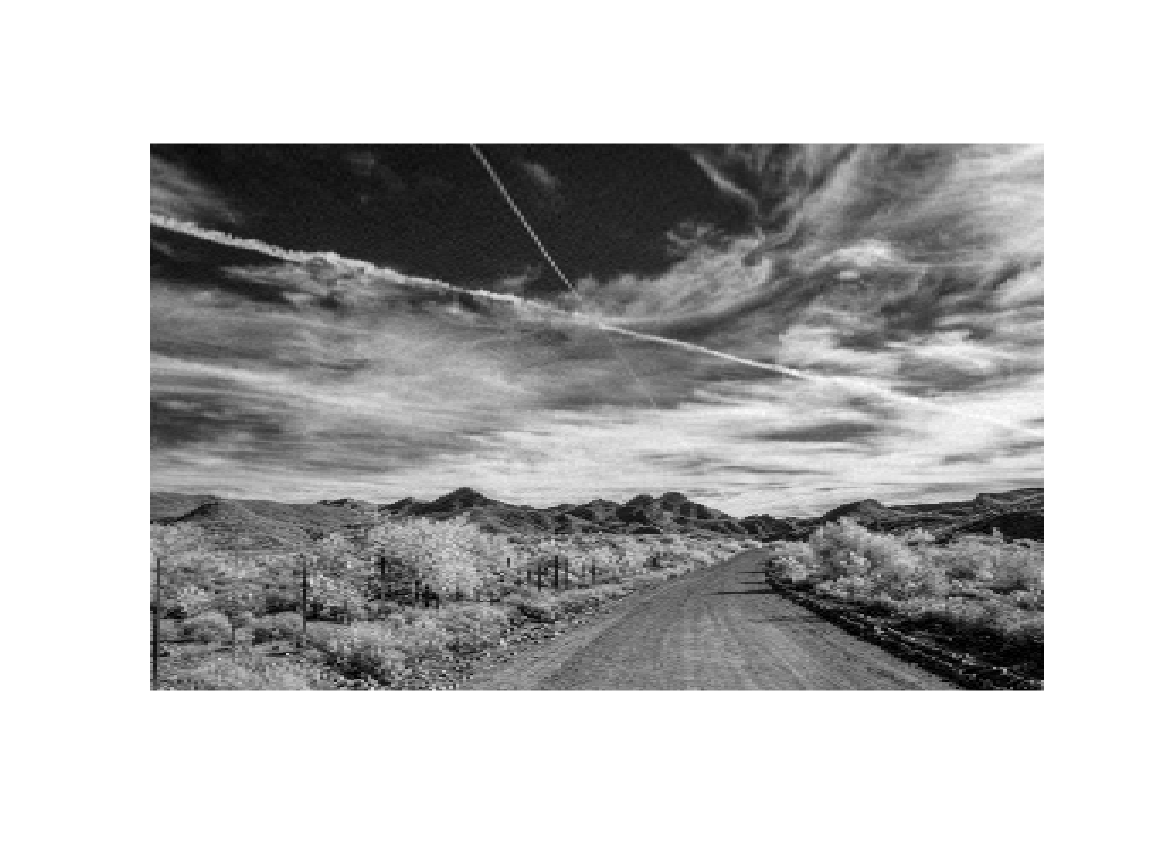

%Rank 160 has the best compression rate approximatley = 10.
imshow(A160)

%Function for calculating RSME
RSME160 = norm(double(A)-double(A160),'fro')/(2583 * 4220)

RSME160 = 0.0025

%CR = 25 approx
CR = (2583*4220)/(64*(2583 + 4220 + 1))

CR = 25.0318


A64 = U(:,1:64) * S(1:64, 1:64) * V(:,1:64)'

A64 =    24.9993   24.3447   22.0100   22.2062   21.9511   21.9226   23.0593   23.7963   24.8462   25.9894   26.7873   26.7581   29.3863   28.6561   28.2635   29.5940   28.3809   30.4921   31.8328   31.1595   29.1047   31.0961   31.7680   31.5461   30.3413   31.3344   31.1357   32.1078   31.2491   29.7296   27.4520   26.4432   26.7583   25.9210   25.5370   26.1199   27.6600   28.4041   26.5367   25.5173   24.1230   21.3904   20.4929   19.7726   19.5011   19.5538   19.9493   20.4600   20.6791   20.5087
   25.2032   24.4691   22.2505   22.4141   22.3977   22.5232   23.5883   24.2551   25.3147   26.4123   27.2995   27.3271   29.8436   29.3503   29.1327   30.6361   29.5202   31.4041   32.7744   32.0377   30.0367   32.2936   33.0550   32.5480   31.2241   32.0171   31.5277   32.2739   31.0545   29.1236   26.5630   25.4538   25.5998   24.7500   24.4515   24.9215   26.6027   27.5087   25.6768   24.7687   23.3070   20.4637   19.3158   18.7045   18.2966   18.4468   18.7208   19.3513   19.6339   

%Verifying rank 64
rank(A64)

ans = 64


A64 = uint8(round(A64))

A64 = 2583×4220 uint8 matrix
   25   24   22   22   22   22   23   24   25   26   27   27   29   29   28   30   28   30   32   31   29   31   32   32   30   31   31   32   31   30   27   26   27   26   26   26   28   28   27   26   24   21   20   20   20   20   20   20   21   21
   25   24   22   22   22   23   24   24   25   26   27   27   30   29   29   31   30   31   33   32   30   32   33   33   31   32   32   32   31   29   27   25   26   25   24   25   27   28   26   25   23   20   19   19   18   18   19   19   20   20
   24   23   21   21   21   21   22   23   24   25   26   26   29   28   28   29   28   30   31   30   28   30   31   31   30   31   31   32   31   29   27   26   26   25   24   25   26   27   26   25   24   21   20   19   19   19   19   20   20   20
   24   24   22   22   22   22   23   24   25   26   27   27   29   28   28   29   27   29   31   30   28   30   31   31   30   31   31   32   31   30   28   28   27   27   26   27   28   29   28   27   26   23   22   

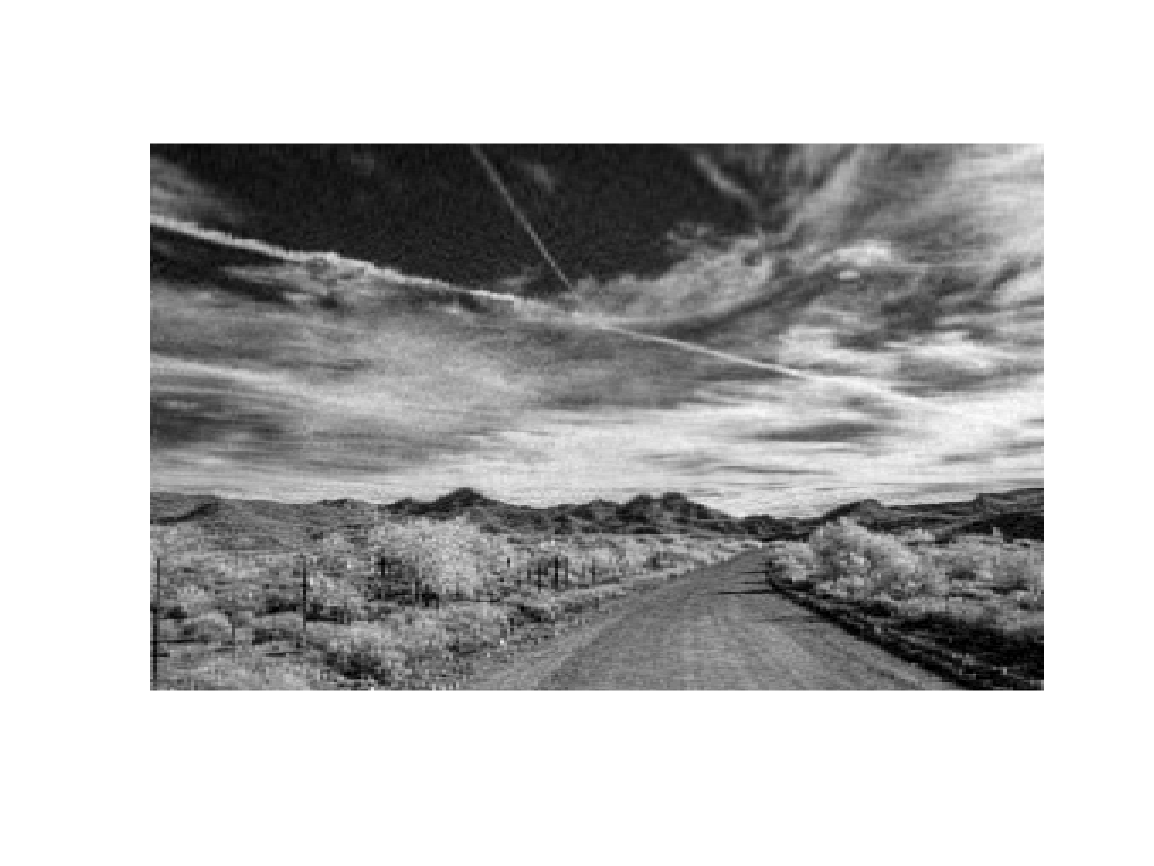

%Displaying image with a compression rate 25, rank 64.
imshow(A64)

% Function for calculating RSME
RSME64 = norm(double(A)-double(A64),'fro')/(2583 * 4220)

RSME64 = 0.0037


%CR = 75 approx
CR = (2583 * 4220)/(21*(2583 + 4220 + 1))

CR = 76.2875


A21 = U(:,1:21) * S(1:21, 1:21) * V(:,1:21)'

A21 =    26.2163   25.6337   24.9907   25.1005   25.5472   26.3732   27.4089   27.1685   28.3767   28.4610   29.3357   28.8873   30.1687   30.7089   30.4488   31.8447   31.9611   34.0456   36.2978   38.0774   39.2434   42.3483   43.8340   45.5040   45.7402   47.4669   46.7603   47.5103   45.7526   43.7189   41.2253   39.5044   38.1118   36.3641   35.9445   34.8835   35.0819   34.9268   34.2277   34.0051   33.1421   31.4119   30.2820   29.0001   29.1654   28.3915   28.2940   28.3111   28.0479   27.6909
   26.5129   25.9007   25.2598   25.3699   25.8707   26.7271   27.7391   27.5112   28.6565   28.6614   29.5233   29.0463   30.2953   30.8705   30.5817   31.8948   31.8117   33.7085   35.7961   37.5041   38.7128   41.8840   43.4488   45.0596   45.2589   46.9803   46.2967   47.0853   45.2755   43.1982   40.7189   38.9485   37.5761   35.8426   35.4324   34.4200   34.6329   34.5466   33.9050   33.7481   32.9846   31.3233   30.1527   28.9029   29.0781   28.3537   28.2746   28.2431   27.9409   

%Verify rank 21
A21 = uint8(round(A21))

A21 = 2583×4220 uint8 matrix
   26   26   25   25   26   26   27   27   28   28   29   29   30   31   30   32   32   34   36   38   39   42   44   46   46   47   47   48   46   44   41   40   38   36   36   35   35   35   34   34   33   31   30   29   29   28   28   28   28   28
   27   26   25   25   26   27   28   28   29   29   30   29   30   31   31   32   32   34   36   38   39   42   43   45   45   47   46   47   45   43   41   39   38   36   35   34   35   35   34   34   33   31   30   29   29   28   28   28   28   28
   26   26   25   25   26   27   28   27   29   29   29   29   30   31   31   32   32   34   36   37   39   42   43   45   45   47   47   47   46   44   41   39   38   36   36   35   35   35   34   34   33   31   30   29   29   28   28   28   28   27
   27   27   26   26   27   27   28   28   29   29   30   30   31   32   31   33   33   35   37   39   40   43   44   46   46   47   46   47   45   44   42   40   39   37   37   36   36   36   35   35   34   33   32   

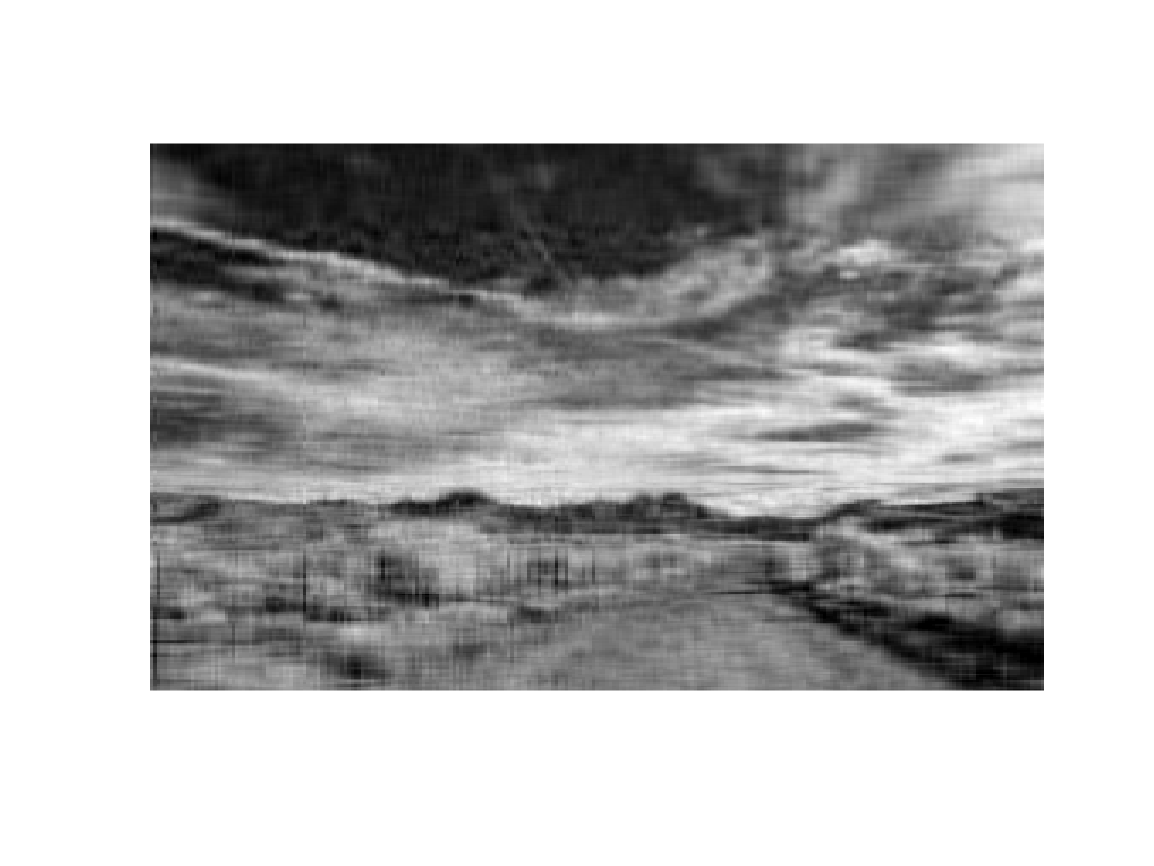

%Showing last rank
% CR = approx 75 will have the worst quality image. 
imshow(A21)

**Explain: Displaying the last rank should be the blurriest version of the image thusfar. All I did for this was use a different value for k to get a different compression ratio. Using different compression ratios from the instructions (CR = approx 10, 25, and 75). From the different compression ratios, the quality is reduced drastically with a compression rate of  25 and 75.  The best compression rate would have to be 10, followed by 2, 25, and last 75. **

**I would recommend a compression of 10.**